x_max = 55;
N_max_gr = 8;
gamma0 = 0;
gamma1 = 1;
gamma2 = 3;

x_eff = 11.8;
x_eff_real = 16;
psi = 0.96;
psi_real = 1.008;
A = [1.0075 1.0095 1.01]';
A_real = [1.0018 1.016 1.009]';
% I'm not going to bother writing out the group number bit since it will
% cancel with the 10
B = [1.65 2.07 2.47]';
B_real = [1.6969 2.2175 1.6709]';
lambda = 700;

x_con_init = [20 22 25 27 17]; 
x_aux_init = [6 6 7 7 8];

parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

parameters_pred = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff, ...
    'psi', psi, ...
    'A', A, ...
    'B', B, ...
    'lambda', lambda);


Np = ;
parameters = parameters_real;

xk = [20;6];
[a,b,c] = functionForAll(Np, xk, parameters, 0)

a =    21.7329
    6.0000


b = 0

c = 156.5003

## Real 2.5

run = true;
if run
    finduOpt = @(xk) functionForAll(Np, xk, parameters_pred, -1);
    realUpdate = @(xk, uk) functionForAll(Np, xk, parameters_real, uk);
    
    
    %[x_next, u_opt, J_opt] = realUpdate(xk, 0)
    
    T_end = 40; 
    
    xk = zeros(2,5, T_end + 1); % xcon/xaux, section, time
    u_k = zeros(5,T_end+1)
    xk(:, :, 1) = [x_con_init ; x_aux_init]; % Set initial conditions
    
    tic
    for i = 2:T_end+1
        disp("x_k = " + num2str(xk(:,:,i-1)))
        disp("time_elapsed = " + num2str(toc) + "seconds")
        disp("time step " + num2str(i-1) + " of " + num2str(T_end))
        for j = 1:5
            [~,u_k(j,i),~] = finduOpt(xk(:,j,i-1)); 
            [xk(:,j,i), ~, ~] = realUpdate(xk(:,j,i-1), u_k(j,i));
        end
    end
end

u_k =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0

    "x_k = 20  22  25  27  17"
    "x_k =  6   6   7   7   8"



time_elapsed = 0.0099299seconds


time step 1 of 40


    "x_k = 21.7329      23.7365      26.7419      28.7455      18.7275"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.29369seconds


time step 2 of 40


    "x_k = 23.4689      25.4761      28.4869      30.4941      20.4581"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.51311seconds


time step 3 of 40


    "x_k = 25.2081      27.2189      30.2351      33.1995      22.1918"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.73214seconds


time step 4 of 40


    "x_k = 26.9503      28.9648      32.9364      35.9482      23.9287"
    "x_k =       6            6            7            7            8"



time_elapsed = 0.94591seconds


time step 5 of 40


    "x_k = 28.6957      30.7138      35.6809      38.7409      25.6687"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.1485seconds


time step 6 of 40


    "x_k = 30.4443      33.4227      38.4692      41.5783      27.4118"
    "x_k =       6            6            7            7            8"



time_elapsed = 1.3709seconds


time step 7 of 40


    "x_k = 33.1489       36.175      41.3023      25.7829       29.158"
    "x_k =       6            6            7            8            8"



time_elapsed = 1.5789seconds


time step 8 of 40


    "x_k = 35.8968      38.9713      25.5047      27.5262      30.9074"
    "x_k =       6            6            8            8            8"



time_elapsed = 1.7545seconds


time step 9 of 40


    "x_k = 38.6886      41.8123      27.2475      29.2726      33.6194"
    "x_k =       6            6            8            8            8"



time_elapsed = 1.9247seconds


time step 10 of 40


    "x_k = 41.5252      26.0188      28.9934      31.0222      36.3748"
    "x_k =       6            7            8            8            8"



time_elapsed = 2.1567seconds


time step 11 of 40


    "x_k = 25.7294      27.7626      30.7425      33.7361      39.1743"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.3526seconds


time step 12 of 40


    "x_k = 27.4726      29.5094      33.4519      36.4934      42.0186"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.5129seconds


time step 13 of 40


    "x_k = 29.2189      31.2595      36.2046      39.2948            0"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.6707seconds


time step 14 of 40


    "x_k = 30.9684      33.9771      39.0014       42.141       1.6969"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.8205seconds


time step 15 of 40


    "x_k = 33.6814      36.7382      41.8429            0      3.39685"
    "x_k =       7            7            8            8            8"



time_elapsed = 2.9814seconds


time step 16 of 40


    "x_k = 36.4378      39.5436            0       1.6969      5.09987"
    "x_k =       7            7            8            8            8"



time_elapsed = 3.1334seconds


time step 17 of 40


    "x_k = 39.2383      42.3938       1.6969      3.39685      6.80595"
    "x_k =       7            7            8            8            8"



time_elapsed = 3.2682seconds


time step 18 of 40


    "x_k = 42.0836      26.6049      3.39685      5.09987       8.5151"
    "x_k =       7            8            8            8            8"



time_elapsed = 3.3909seconds


time step 19 of 40


    "x_k = 26.2923      28.3497      5.09987      6.80595      10.2273"
    "x_k =       8            8            8            8            8"



time_elapsed = 3.4803seconds


time step 20 of 40


    "x_k = 28.0365      30.0976      6.80595       8.5151      11.9426"
    "x_k =       8            8            8            8            8"



time_elapsed = 3.6025seconds


time step 21 of 40


    "x_k = 29.7839      32.7967       8.5151      10.2273       13.661"
    "x_k =       8            8            8            8            8"



time_elapsed = 3.6941seconds


time step 22 of 40


    "x_k = 31.5344      35.5389      10.2273      11.9426      15.3825"
    "x_k =       8            8            8            8            8"



time_elapsed = 3.7916seconds


time step 23 of 40


    "x_k = 34.2565      38.3251      11.9426       13.661      17.1071"
    "x_k =       8            8            8            8            8"



time_elapsed = 3.89seconds


time step 24 of 40


    "x_k = 37.0221      41.1558       13.661      15.3825      18.8348"
    "x_k =       8            8            8            8            8"



time_elapsed = 4.0039seconds


time step 25 of 40


    "x_k = 39.8319            0      15.3825      17.1071      20.5656"
    "x_k =       8            8            8            8            8"



time_elapsed = 4.1175seconds


time step 26 of 40


    "x_k = 0       1.6969      17.1071      18.8348      22.2995"
    "x_k = 8            8            8            8            8"



time_elapsed = 4.2163seconds


time step 27 of 40


    "x_k = 1.6969      3.39685      18.8348      20.5656      24.0366"
    "x_k =      8            8            8            8            8"



time_elapsed = 4.3202seconds


time step 28 of 40


    "x_k = 3.39685      5.09987      20.5656      22.2995      25.7767"
    "x_k =       8            8            8            8            8"



time_elapsed = 4.4147seconds


time step 29 of 40


    "x_k = 5.09987      6.80595      22.2995      24.0366        27.52"
    "x_k =       8            8            8            8            8"



time_elapsed = 4.5081seconds


time step 30 of 40


    "x_k = 6.80595       8.5151      24.0366      25.7767      29.2665"
    "x_k =       8            8            8            8            8"



time_elapsed = 4.5894seconds


time step 31 of 40


    "x_k = 8.5151      10.2273      25.7767        27.52       31.016"
    "x_k =      8            8            8            8            8"



time_elapsed = 4.71seconds


time step 32 of 40


    "x_k = 10.2273      11.9426        27.52      29.2665      33.7298"
    "x_k =       8            8            8            8            8"



time_elapsed = 4.7878seconds


time step 33 of 40


    "x_k = 11.9426       13.661      29.2665       31.016       36.487"
    "x_k =       8            8            8            8            8"



time_elapsed = 4.8879seconds


time step 34 of 40


    "x_k = 13.661      15.3825       31.016      33.7298      39.2883"
    "x_k =      8            8            8            8            8"



time_elapsed = 4.9973seconds


time step 35 of 40


    "x_k = 15.3825      17.1071      33.7298       36.487      42.1344"
    "x_k =       8            8            8            8            8"



time_elapsed = 5.1087seconds


time step 36 of 40


    "x_k = 17.1071      18.8348       36.487      39.2883            0"
    "x_k =       8            8            8            8            8"



time_elapsed = 5.2298seconds


time step 37 of 40


    "x_k = 18.8348      20.5656      39.2883      42.1344       1.6969"
    "x_k =       8            8            8            8            8"



time_elapsed = 5.3741seconds


time step 38 of 40


    "x_k = 20.5656      22.2995      42.1344            0      3.39685"
    "x_k =       8            8            8            8            8"



time_elapsed = 5.5562seconds


time step 39 of 40


    "x_k = 22.2995      24.0366            0       1.6969      5.09987"
    "x_k =       8            8            8            8            8"



time_elapsed = 5.695seconds


time step 40 of 40


## chatgpt plotting

t = 1:T_end+1;

figure;
bigPlot = tiledlayout(5,1,'TileSpacing','compact','Padding','compact');

xlabel(bigPlot,'Time step')
ylabel(bigPlot,'Average length of squats in rail section')

for j = 1:5

    ax = nexttile;
    hold(ax,'on')
    grid(ax,'on')

    y_cont = squeeze(xk(1,j,:));
    y_disc = squeeze(xk(2,j,:));
    colour_state = squeeze(u_k(j,:));

    % ---------------------------
    % Continuous signal
    % ---------------------------
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    drawnow
    yl = ylim(ax);

    % ---------------------------
    % Background colour regions
    % ---------------------------
    for k = 1:length(t)-1

        switch colour_state(k)

            case 0
                c = [1 0 0]; % red

            case 1
                c = [1 1 0]; % yellow

            case 2
                c = [0 0 1]; % blue

            otherwise
                c = [0.8 0.8 0.8];
        end

        patch(ax,...
            [t(k) t(k+1) t(k+1) t(k)],...
            [yl(1) yl(1) yl(2) yl(2)],...
            c,...
            'FaceAlpha',0.12,...
            'EdgeColor','none',...
            'HandleVisibility','off');   % prevents legend duplication
    end

    % redraw line on top of patches
    yyaxis(ax,'left')
    h_cont = plot(ax,t,y_cont,'k','LineWidth',1.5);

    % ---------------------------
    % Discrete signal
    % ---------------------------
    yyaxis(ax,'right')
    h_disc = stairs(ax,t,y_disc,'LineWidth',1.5);

    % ---------------------------
    % Dummy objects for legend
    % ---------------------------
    h_red    = patch(nan,nan,[1 0 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_yellow = patch(nan,nan,[1 1 0],'FaceAlpha',0.12,'EdgeColor','none');
    h_blue   = patch(nan,nan,[0 0 1],'FaceAlpha',0.12,'EdgeColor','none');

    % ---------------------------
    % Legend
    % ---------------------------
    legend(ax,...
        [h_cont h_disc h_red h_yellow h_blue],...
        {'Average squat length','# grinds since replacement',...
         'Degradation','Grinding','Replacement'},...
        'Location','best')

end

## Real 2.6

function totalCost = doMe(var)
    x_max = 38;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [0;0];
    parameters_real.N_max_gr = N_gr;
    Np = 8;
    T_end = 20; 
    IDs = 1:M:T_end; u = zeros(1,T_end); u(IDs) = 1;
    totalCost = 0;
    for i = 1:T_end
        [xk,~,J] = functionForAll(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        if(xk(2) >= N_gr)
            u(i+1) = 2;
        end
    end 
end
tic
LB = [0,0]; UB = [19, 19];
doMeNow = @doMe;
N_M = ga(doMeNow, 2, zeros(1,2), 0, zeros(1,2) ,0, LB, UB); % took 25 minutes to run, game N_max = 0.54, M = 1.8339

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


N_max_gr = N_M(1);
M = N_M(2);
time = toc;




## testing

function [x, us, totalCost] = doMe2(var)
    x_max = 38;
    N_max_gr = 8;
    gamma0 = 0;
    gamma1 = 1;
    gamma2 = 3;
    
    x_eff_real = 16;
    psi_real = 1.008;
    A_real = [1.0018 1.016 1.009]';
    B_real = [1.6969 2.2175 1.6709]';
    lambda = 700;

    parameters_real = struct( ...
    'x_max', x_max, ...
    'N_max_gr', N_max_gr, ...
    'gamma0', gamma0, ...
    'gamma1', gamma1, ...
    'gamma2', gamma2, ...
    'x_eff', x_eff_real, ...
    'psi', psi_real, ...
    'A', A_real, ...
    'B', B_real, ...
    'lambda', lambda);

    N_gr = var(1); M = round(var(2));
    xk = [0;0];
    parameters_real.N_max_gr = N_gr;
    Np = 1;
    T_end = 20; 
    IDs = 1:M:T_end; u = zeros(1,T_end); u(IDs) = 1;
    totalCost = 0;
    x = zeros(2,T_end);
    us = zeros(1,T_end);
    for i = 1:T_end
        [xk,u_current,J] = functionForAll(Np, xk, parameters_real, u(i));
        totalCost = totalCost + J;
        x(:,i) = xk; us(i) = u_current;
        if(xk(2) >= N_gr)
            u(i+1) = 2;
        end
    end 
end

[xs, us, J] = doMe2([19; 19])

xs =          0    1.6969    3.3969    5.0999    6.8059    8.5151   10.2273   11.9426   13.6610   15.3825   17.1071   18.8348   20.5656   22.2995   24.0366   25.7767   27.5200   29.2665   31.0160   15.1362
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    2.0000


us =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1


J = 1.7083e+03

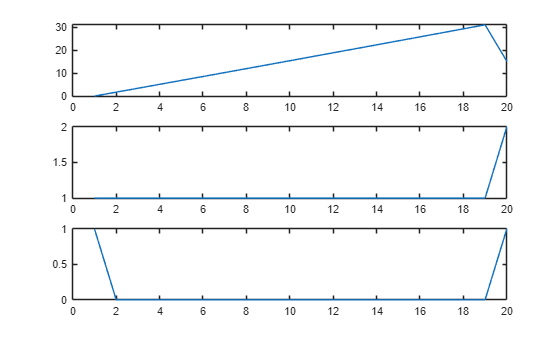


N = size(xs,2);
tiledlayout(3,1)
nexttile
plot(1:N, xs(1,:));
nexttile
plot(1:N, xs(2,:));
nexttile
plot(1:N, us(:));